This script extract frames from seq files, align the frame time with Bpod and generates videos 

Map video frames to bpod using LED_on times (note that missing frames make it impossible to align frame time with frame trigger signals precisely, altougth trigger signals are recorded in wave).

Jianing Yu 12/18/2022

## Step 1:Check videos 

(dont't just 'Run Section', run codes step by step)

m=dir('*.seq')
{m.name}'
% Run this from command window to find out 1) which video file is from side and which
% one is from top. 2) The frames what shows LED-on period, which can be
% used later for drawing ROI. 

sideviews = 2×1 cell array
    {'20220928-11-17-36.000.seq'}
    {'20220928-11-38-59.000.seq'}

PlaySeqFile(m(1).name)
% Note, write down the t range when LED is clearly visible. This helps draw
% the ROI


### Extract frame signals

%
sideviews = [
    {'20220928-11-17-36.000.seq'}
    {'20220928-11-38-59.000.seq'}
    ];
sideviews

ans = 'Please select region of interests'

ans = 'Extracting ......'

ans = '1000s frames extracted  1 '

ans = '1000s frames extracted  2 '

ans = '1000s frames extracted  3 '

ans = '1000s frames extracted  4 '

ans = '1000s frames extracted  5 '

ans = '1000s frames extracted  6 '

ans = '1000s frames extracted  7 '

ans = '1000s frames extracted  8 '

ans = '1000s frames extracted  9 '

ans = '1000s frames extracted 10 '

ans = '1000s frames extracted 11 '

ans = '1000s frames extracted 12 '

ans = '1000s frames extracted 13 '

ans = '1000s frames extracted 14 '

ans = '1000s frames extracted 15 '

ans = '1000s frames extracted 16 '

ans = '1000s frames extracted 17 '

ans = '1000s frames extracted 18 '

ans = '1000s frames extracted 19 '

ans = '1000s frames extracted 20 '

ans = '1000s frames extracted 21 '

ans = '1000s frames extracted 22 '

ans = '1000s frames extracted 23 '

ans = '1000s frames extracted 24 '

ans = '1000s frames extracted 25 '

ans = '1000s frames extracted 26 '

ans = '1000s frames extracted 27 '

ans = '1000s frames extracted 28 '

ans = '1000s frames extracted 29 '

ans = '1000s frames extracted 30 '

ans = '1000s frames extracted 31 '

ans = '1000s frames extracted 32 '

ans = '1000s frames extracted 33 '

ans = '1000s frames extracted 34 '

ans = '1000s frames extracted 35 '

ans = '1000s frames extracted 36 '

ans = '1000s frames extracted 37 '

ans = '1000s frames extracted 38 '

ans = '1000s frames extracted 39 '

ans = '1000s frames extracted 40 '

ans = '1000s frames extracted 41 '

ans = '1000s frames extracted 42 '

ans = '1000s frames extracted 43 '

ans = '1000s frames extracted 44 '

ans = '1000s frames extracted 45 '

ans = '1000s frames extracted 46 '

ans = '1000s frames extracted 47 '

ans = '1000s frames extracted 48 '

ans = '1000s frames extracted 49 '

ans = '1000s frames extracted 50 '

ans = '1000s frames extracted 51 '

ans = '1000s frames extracted 52 '

ans = '1000s frames extracted 53 '

ans = '1000s frames extracted 54 '

ans = '1000s frames extracted 55 '

ans = '1000s frames extracted 56 '

ans = '1000s frames extracted 57 '

ans = '1000s frames extracted 58 '

ans = '1000s frames extracted 59 '

ans = '1000s frames extracted 60 '

ans = '1000s frames extracted 61 '

ans = '1000s frames extracted 62 '

ans = '1000s frames extracted 63 '

ans = '1000s frames extracted 64 '

ans = '1000s frames extracted 65 '

ans = '1000s frames extracted 66 '

ans = '1000s frames extracted 67 '

ans = '1000s frames extracted 68 '

ans = '1000s frames extracted 69 '

ans = '1000s frames extracted 70 '

ans = '1000s frames extracted 71 '

ans = '1000s frames extracted 72 '

ans = '1000s frames extracted 73 '

ans = '1000s frames extracted 74 '

ans = '1000s frames extracted 75 '

ans = '1000s frames extracted 76 '

ans = '1000s frames extracted 77 '

ans = '1000s frames extracted 78 '

ans = '1000s frames extracted 79 '

ans = '1000s frames extracted 80 '

ans = '1000s frames extracted 81 '

ans = '1000s frames extracted 82 '

ans = '1000s frames extracted 83 '

ans = '1000s frames extracted 84 '

ans = '1000s frames extracted 85 '

ans = '1000s frames extracted 86 '

ans = '1000s frames extracted 87 '

ans = '1000s frames extracted 88 '

ans = '1000s frames extracted 89 '

ans = '1000s frames extracted 90 '

ans = '1000s frames extracted 91 '

ans = '1000s frames extracted 92 '

ans = '1000s frames extracted 93 '

ans = '1000s frames extracted 94 '

ans = '1000s frames extracted 95 '

ans = '1000s frames extracted 96 '

ans = '1000s frames extracted 97 '

ans = '1000s frames extracted 98 '

ans = '1000s frames extracted 99 '

ans = '1000s frames extracted 100 '

ans = '1000s frames extracted 101 '

ans = '1000s frames extracted 102 '

ans = '1000s frames extracted 103 '

ans = '1000s frames extracted 104 '

ans = '1000s frames extracted 105 '

ans = '1000s frames extracted 106 '

ans = '1000s frames extracted 107 '

ans = '1000s frames extracted 108 '

ans = '1000s frames extracted 109 '

ans = '1000s frames extracted 110 '

ans = '1000s frames extracted 111 '

ans = '1000s frames extracted 112 '

ans = '1000s frames extracted 113 '

ans = '1000s frames extracted 114 '

ans = '1000s frames extracted 115 '

ans = '1000s frames extracted 116 '

ans = '1000s frames extracted 117 '

ans = '1000s frames extracted 118 '

ans = '1000s frames extracted 119 '

ans = '1000s frames extracted 120 '

ans = '1000s frames extracted  1 '

ans = '1000s frames extracted  2 '

ans = '1000s frames extracted  3 '

ans = '1000s frames extracted  4 '

ans = '1000s frames extracted  5 '

ans = '1000s frames extracted  6 '

ans = '1000s frames extracted  7 '

ans = '1000s frames extracted  8 '

ans = '1000s frames extracted  9 '

ans = '1000s frames extracted 10 '

ans = '1000s frames extracted 11 '

ans = '1000s frames extracted 12 '

ans = '1000s frames extracted 13 '

ans = '1000s frames extracted 14 '

ans = '1000s frames extracted 15 '

ans = '1000s frames extracted 16 '

ans = '1000s frames extracted 17 '

ans = '1000s frames extracted 18 '

ans = '1000s frames extracted 19 '

ans = '1000s frames extracted 20 '

ans = '1000s frames extracted 21 '

ans = '1000s frames extracted 22 '

ans = '1000s frames extracted 23 '

ans = '1000s frames extracted 24 '

ans = '1000s frames extracted 25 '

ans = '1000s frames extracted 26 '

ans = '1000s frames extracted 27 '

ans = '1000s frames extracted 28 '

ans = '1000s frames extracted 29 '

ans = '1000s frames extracted 30 '

ans = '1000s frames extracted 31 '

ans = '1000s frames extracted 32 '

ans = '1000s frames extracted 33 '

ans = '1000s frames extracted 34 '

ans = '1000s frames extracted 35 '

ans = '1000s frames extracted 36 '

ans = '1000s frames extracted 37 '

ans = '1000s frames extracted 38 '

ans = '1000s frames extracted 39 '

ans = '1000s frames extracted 40 '

ans = '1000s frames extracted 41 '

ans = '1000s frames extracted 42 '

ans = '1000s frames extracted 43 '

ans = '1000s frames extracted 44 '

ans = '1000s frames extracted 45 '

ans = '1000s frames extracted 46 '

ans = '1000s frames extracted 47 '

ans = '1000s frames extracted 48 '

ans = '1000s frames extracted 49 '

ans = '1000s frames extracted 50 '

ans = '1000s frames extracted 51 '

ans = '1000s frames extracted 52 '

ans = '1000s frames extracted 53 '

ans = '1000s frames extracted 54 '

ans = '1000s frames extracted 55 '

ans = '1000s frames extracted 56 '

ans = '1000s frames extracted 57 '

ans = '1000s frames extracted 58 '

ans = '1000s frames extracted 59 '

ans = '1000s frames extracted 60 '

ans = '1000s frames extracted 61 '

ans = '1000s frames extracted 62 '

ans = '1000s frames extracted 63 '

ans = '1000s frames extracted 64 '

ans = '1000s frames extracted 65 '

ans = '1000s frames extracted 66 '

ans = '1000s frames extracted 67 '

ans = '1000s frames extracted 68 '

ans = '1000s frames extracted 69 '

ans = '1000s frames extracted 70 '

ans = '1000s frames extracted 71 '

ans = '1000s frames extracted 72 '

ans = '1000s frames extracted 73 '

ans = '1000s frames extracted 74 '

ans = '1000s frames extracted 75 '

ans = '1000s frames extracted 76 '

ans = '1000s frames extracted 77 '

ans = '1000s frames extracted 78 '

ans = '1000s frames extracted 79 '

ans = '1000s frames extracted 80 '

ans = '1000s frames extracted 81 '

ans = '1000s frames extracted 82 '

ans = '1000s frames extracted 83 '

ans = '1000s frames extracted 84 '

ans = '1000s frames extracted 85 '

ans = '1000s frames extracted 86 '

ans = '1000s frames extracted 87 '

ans = '1000s frames extracted 88 '

ans = '1000s frames extracted 89 '

ans = '1000s frames extracted 90 '

ans = '1000s frames extracted 91 '

ans = '1000s frames extracted 92 '

ans = '1000s frames extracted 93 '

ans = '1000s frames extracted 94 '

ans = '1000s frames extracted 95 '

ans = '1000s frames extracted 96 '

ans = '1000s frames extracted 97 '

ans = '1000s frames extracted 98 '

ans = '1000s frames extracted 99 '

ans = '1000s frames extracted 100 '

ans = '1000s frames extracted 101 '

ans = '1000s frames extracted 102 '

ans = '1000s frames extracted 103 '

ans = '1000s frames extracted 104 '

ans = '1000s frames extracted 105 '

ans = '1000s frames extracted 106 '

ans = '1000s frames extracted 107 '

ans = '1000s frames extracted 108 '

ans = '1000s frames extracted 109 '

ans = '1000s frames extracted 110 '

ans = '1000s frames extracted 111 '

ans = '1000s frames extracted 112 '

ans = '1000s frames extracted 113 '

ans = '1000s frames extracted 114 '

ans = '1000s frames extracted 115 '

ans = '1000s frames extracted 116 '

ans = '1000s frames extracted 117 '

ans = '1000s frames extracted 118 '

ans = '1000s frames extracted 119 '

ans = '1000s frames extracted 120 '

ans = '1000s frames extracted 121 '

ans = '1000s frames extracted 122 '

ans = '1000s frames extracted 123 '

ans = '1000s frames extracted 124 '

ans = '1000s frames extracted 125 '

ans = '1000s frames extracted 126 '

ans = '1000s frames extracted 127 '

ans = '1000s frames extracted 128 '

ans = '1000s frames extracted 129 '

ans = '1000s frames extracted 130 '

ans = '1000s frames extracted 131 '

ans = '1000s frames extracted 132 '

ans = '1000s frames extracted 133 '

ans = '1000s frames extracted 134 '

ans = '1000s frames extracted 135 '

ans = '1000s frames extracted 136 '

ans = '1000s frames extracted 137 '

ans = '1000s frames extracted 138 '

ans = '1000s frames extracted 139 '

ans = '1000s frames extracted 140 '

ans = '1000s frames extracted 141 '

ans = '1000s frames extracted 142 '

ans = '1000s frames extracted 143 '

ans = '1000s frames extracted 144 '

ans = '1000s frames extracted 145 '

ans = '1000s frames extracted 146 '

ans = '1000s frames extracted 147 '

ans = '1000s frames extracted 148 '

ans = '1000s frames extracted 149 '

ans = '1000s frames extracted 150 '

ans = '1000s frames extracted 151 '

ans = '1000s frames extracted 152 '

ans = '1000s frames extracted 153 '

ans = '1000s frames extracted 154 '

ans = '1000s frames extracted 155 '

ans = '1000s frames extracted 156 '

ans = '1000s frames extracted 157 '

ans = '1000s frames extracted 158 '

ans = '1000s frames extracted 159 '

ans = '1000s frames extracted 160 '

ans = '1000s frames extracted 161 '

ans = '1000s frames extracted 162 '

ans = '1000s frames extracted 163 '

ans = '1000s frames extracted 164 '

ans = '1000s frames extracted 165 '

ans = '1000s frames extracted 166 '

ans = '1000s frames extracted 167 '

ans = '1000s frames extracted 168 '

ans = '1000s frames extracted 169 '

ans = '1000s frames extracted 170 '

ans = '1000s frames extracted 171 '

ans = '1000s frames extracted 172 '

ans = '1000s frames extracted 173 '

ans = '1000s frames extracted 174 '

ans = '1000s frames extracted 175 '

ans = '1000s frames extracted 176 '

ans = '1000s frames extracted 177 '

ans = '1000s frames extracted 178 '

ans = '1000s frames extracted 179 '

ans = '1000s frames extracted 180 '

Elapsed time is 3297.296685 seconds.


FrameInfo = struct with fields:
          tframe: [0 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240 250 260 270 280 290 300 310 320 330 340 350 360 370 380 390 400 410 420 430 440 450 460 470 480 490 500 510 520 530 540 550 560 570 580 590 600 … ]
            mask: [900×1000 logical]
             ROI: [4134674 4137084 4139323 4140341 4141433 4140569 4136586 4135441 4134101 4134906 4134049 4133349 4134268 4136679 4136165 4137471 4138202 4137895 4136453 4134197 4130923 4127615 4125441 4121928 4122165 4121610 4122802 4122249 4122883 … ]
      SeqVidFile: {2×1 cell}
     SeqFileIndx: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 … ]
    SeqFrameIndx: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 

topviews =[
    {'20220928-11-17-37.000.seq'}
    {'20220928-11-39-01.000.seq'}
    ];

drawnow


Elapsed time is 0.031881 seconds.


t_check = [342.25 342.35]; % this was from PlayVideo

          tframe: [0 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 … ]
            mask: [900×1000 logical]
             ROI: [4134674 4137084 4139323 4140341 4141433 4140569 4136586 … ]
      SeqVidFile: {2×1 cell}
     SeqFileIndx: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 … ]
    SeqFrameIndx: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 … ]


Select threshold, end selection by right click
Select mulitple points to define a decision boundary, end selection by right click


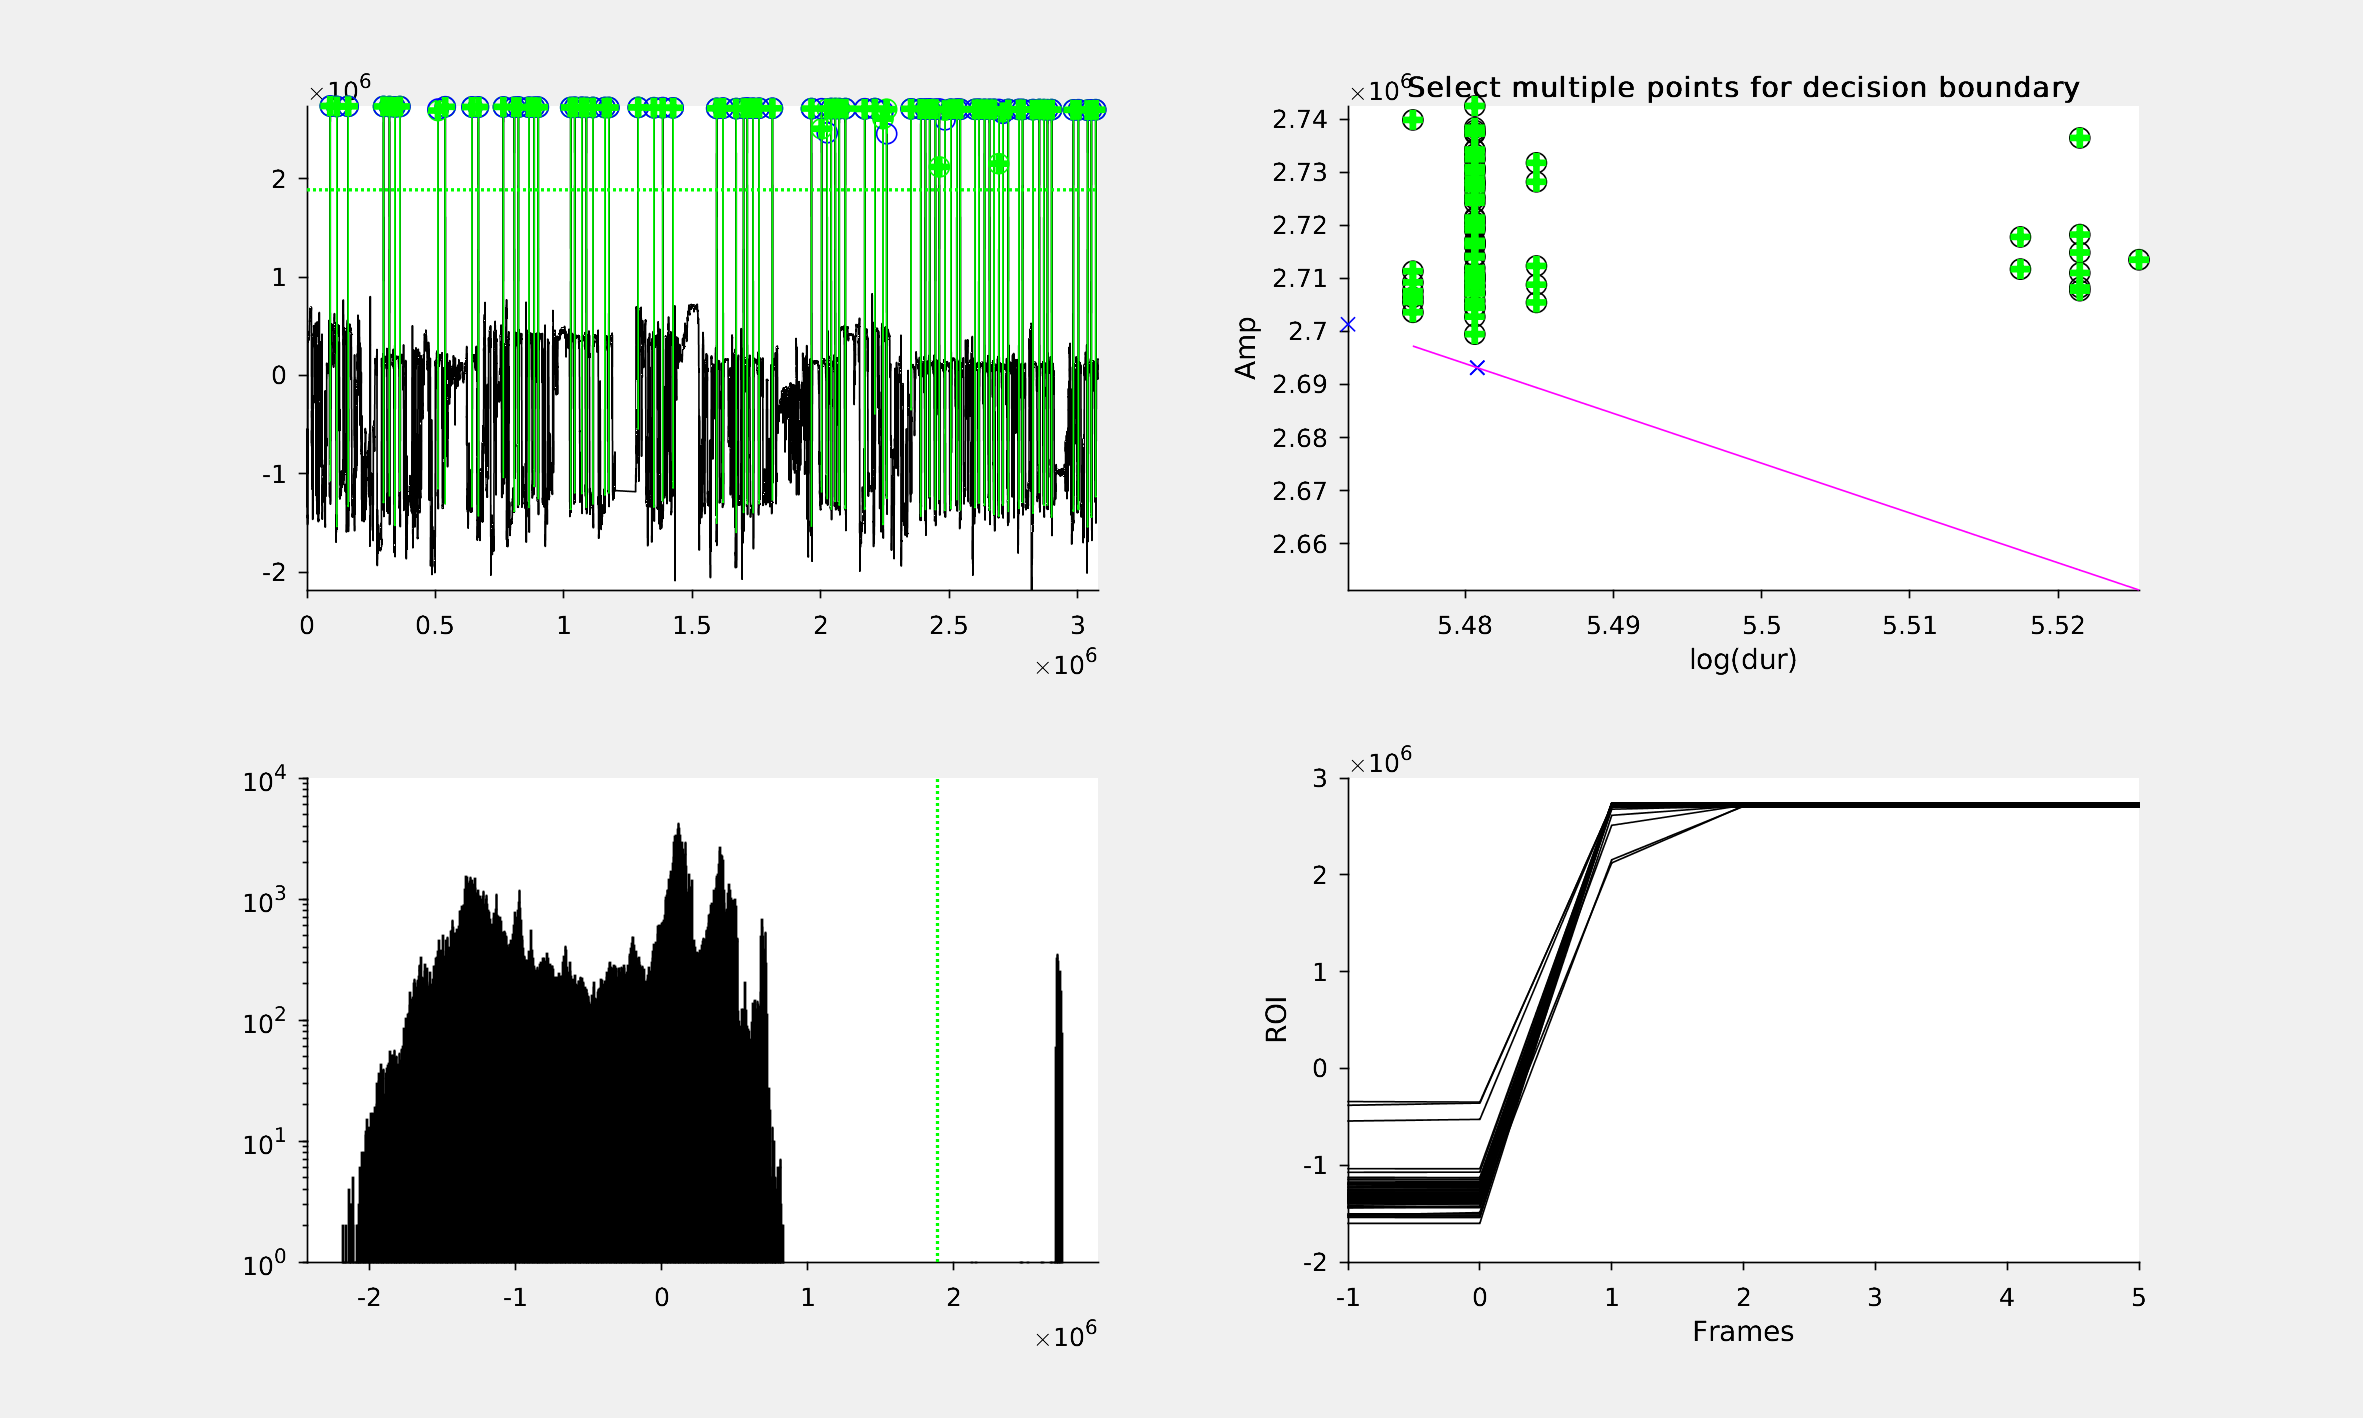

tic
FrameInfo = GetSeqFrameInfo(sideviews, t_check*100)

## Get ROI and frame time

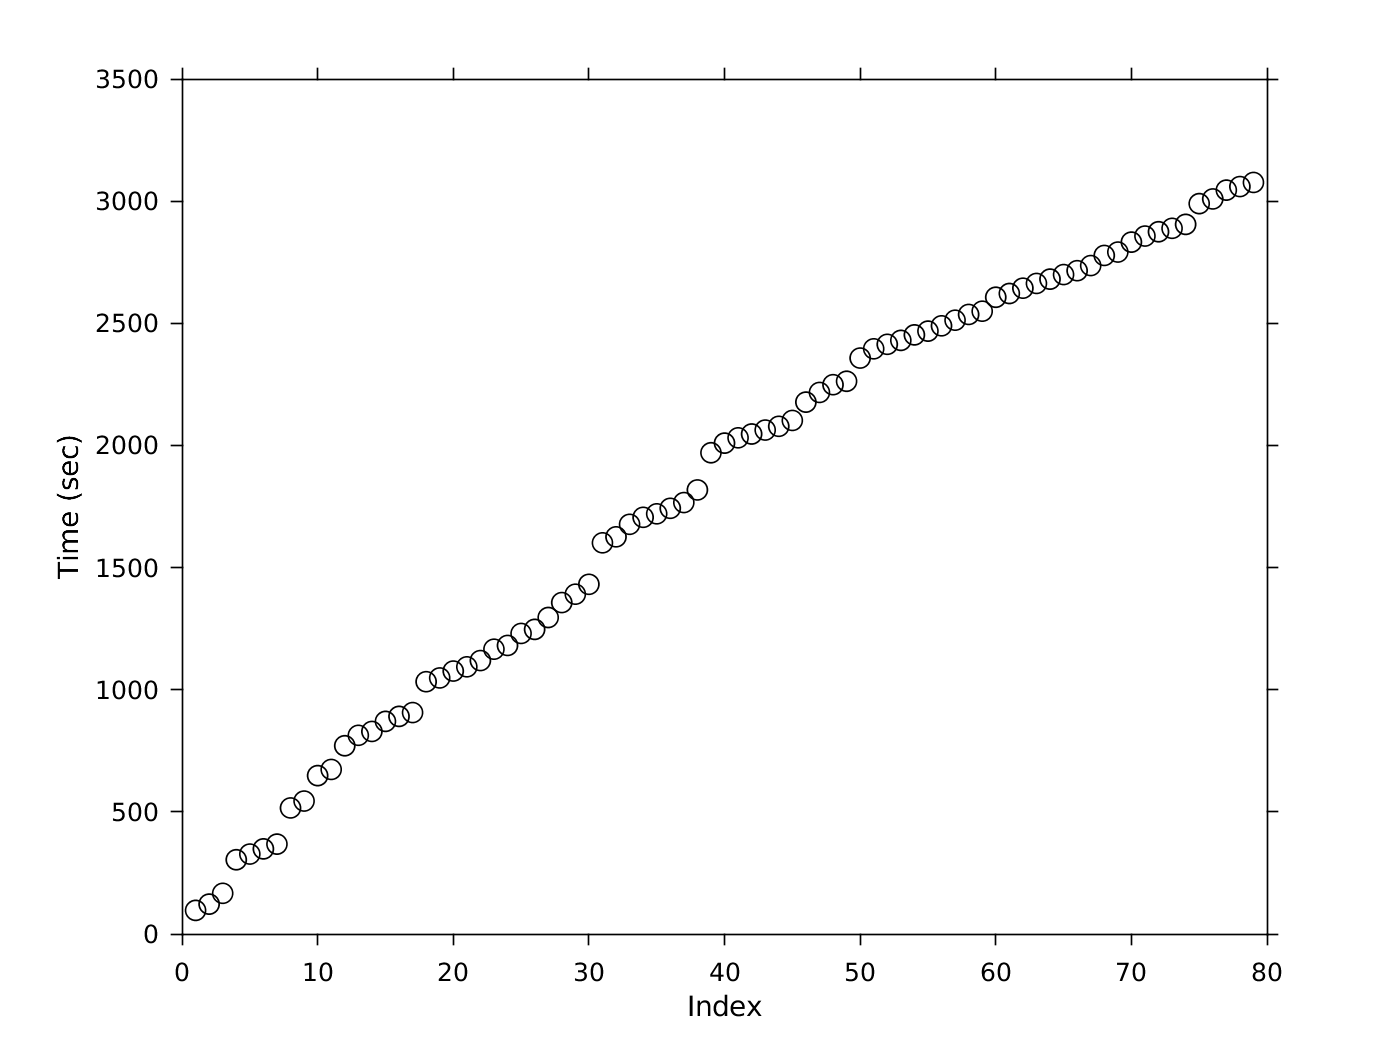


tic
% GetSeqFrameInfo([], t_check);
load('FrameInfo.mat')

#############################
########## Please wait #########
#############################
Elapsed time is 0.513065 seconds.


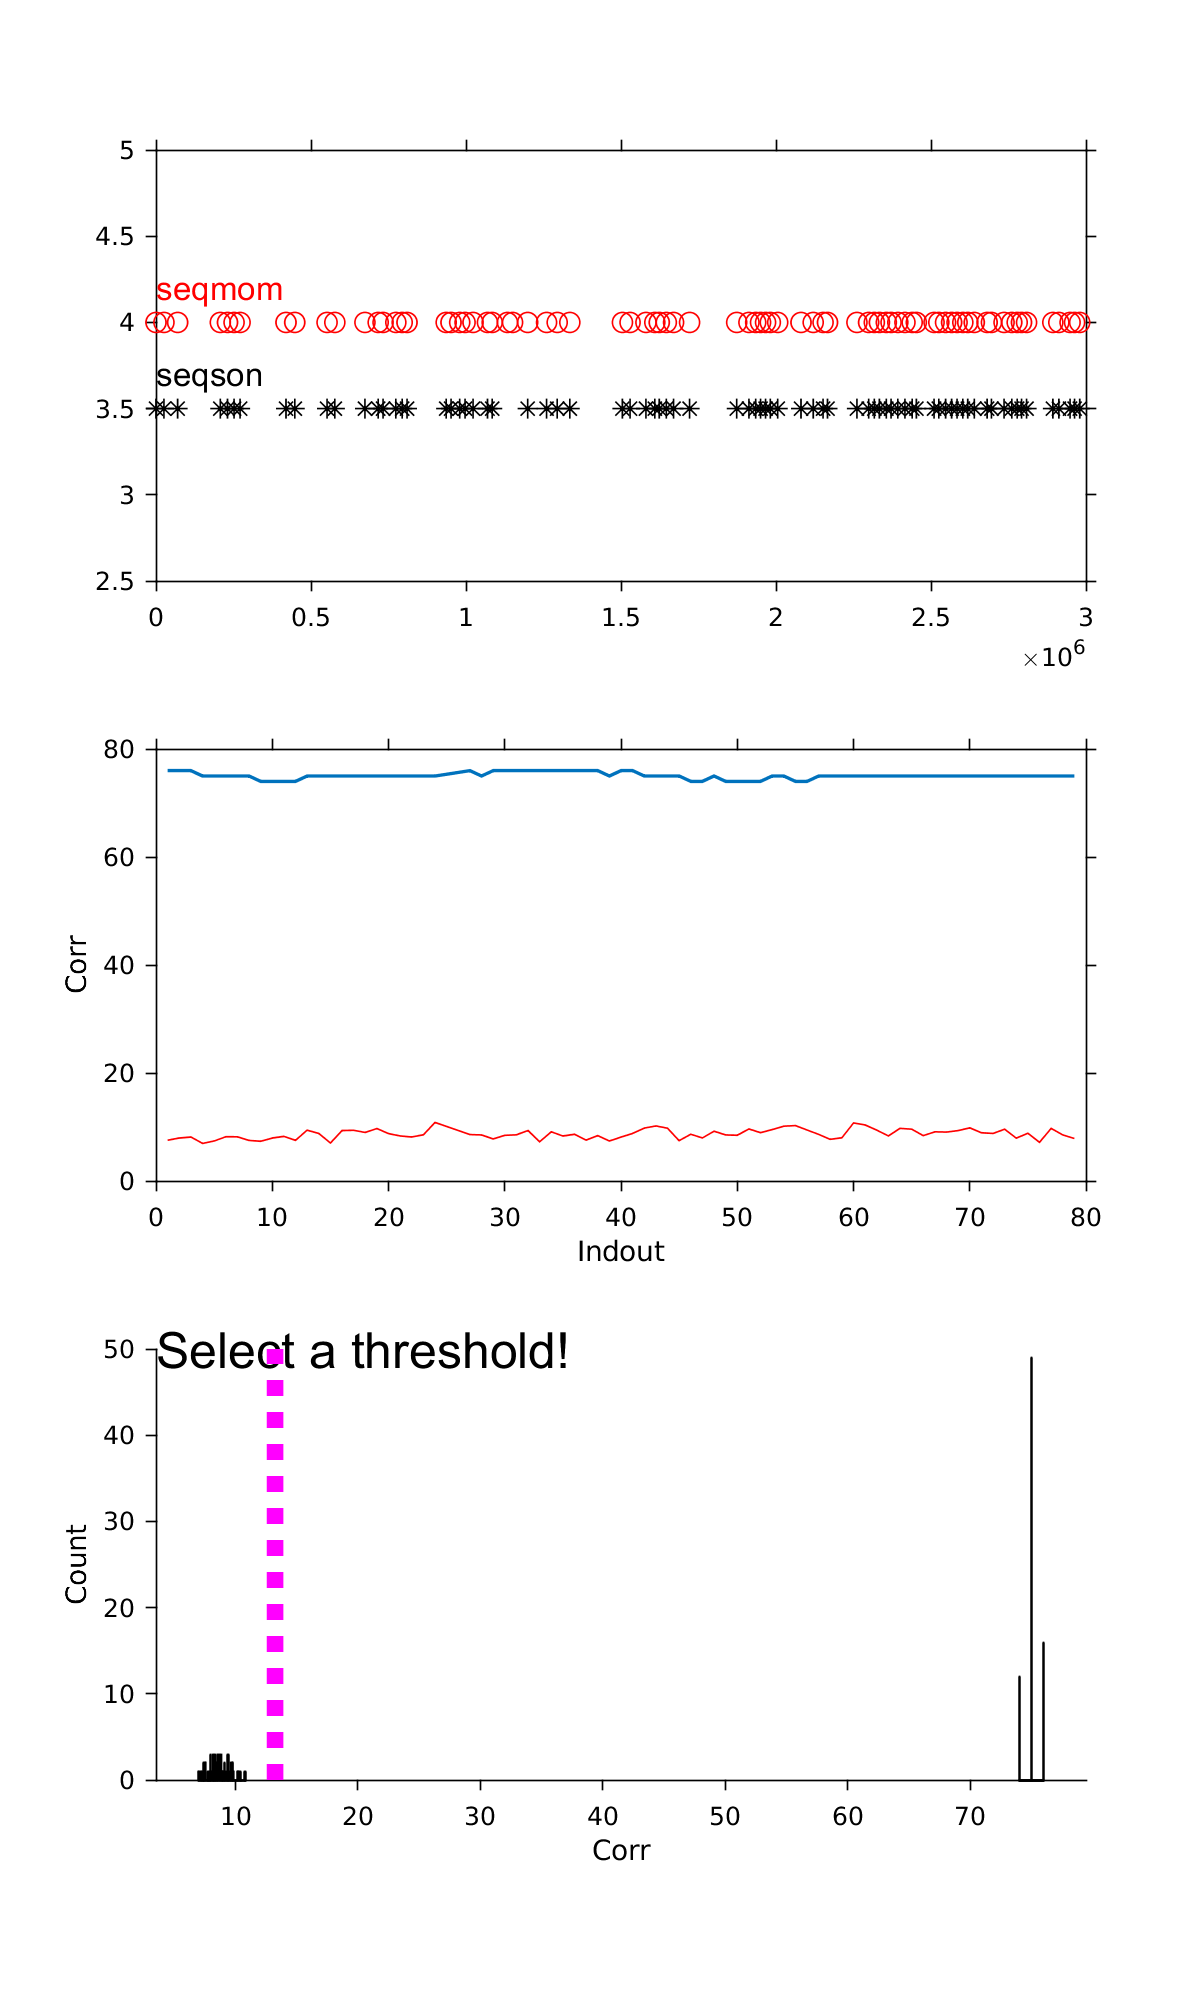

toc
disp(FrameInfo)
% Extract LED time from ROI dynamics

tLEDon          =       FindLEDon(FrameInfo.tframe, FrameInfo.ROI); % in ms

% Load r for alignment
load('RTarrayAll.mat')
tTriggerR = r.Behavior.EventTimings(r.Behavior.EventMarkers == find(strcmp(r.Behavior.Labels, 'Trigger'))); % in ms

## Alignment

- r: trigger signals and release time in uncued trials (10 ms offset)

- LED on time: time of LED on

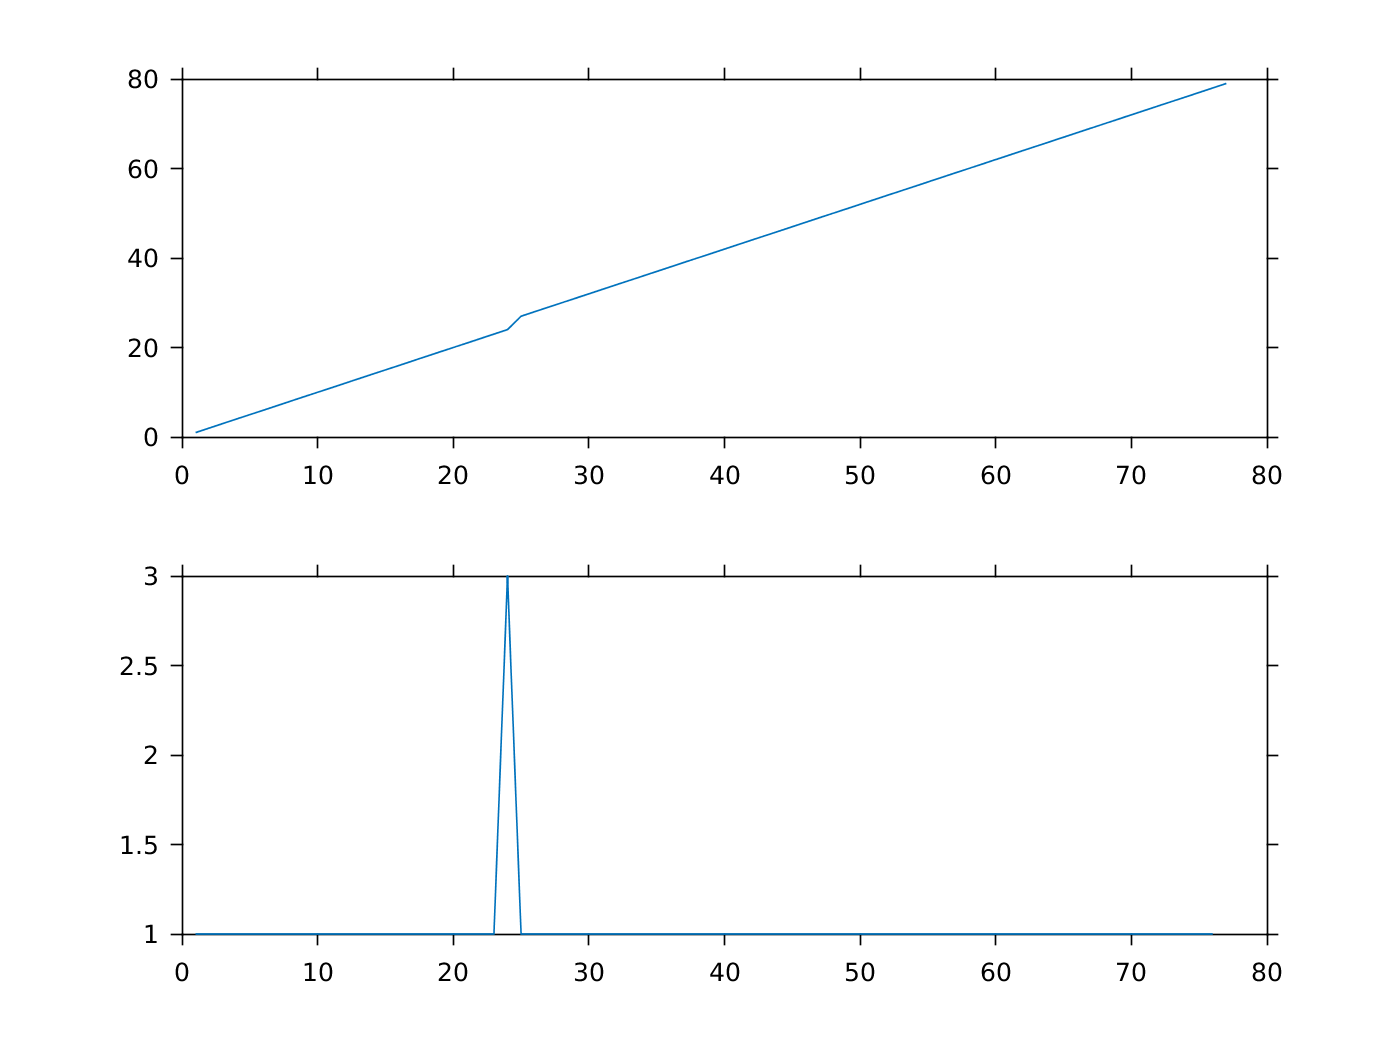

figure; plot(tTriggerR/1000, 'ko')

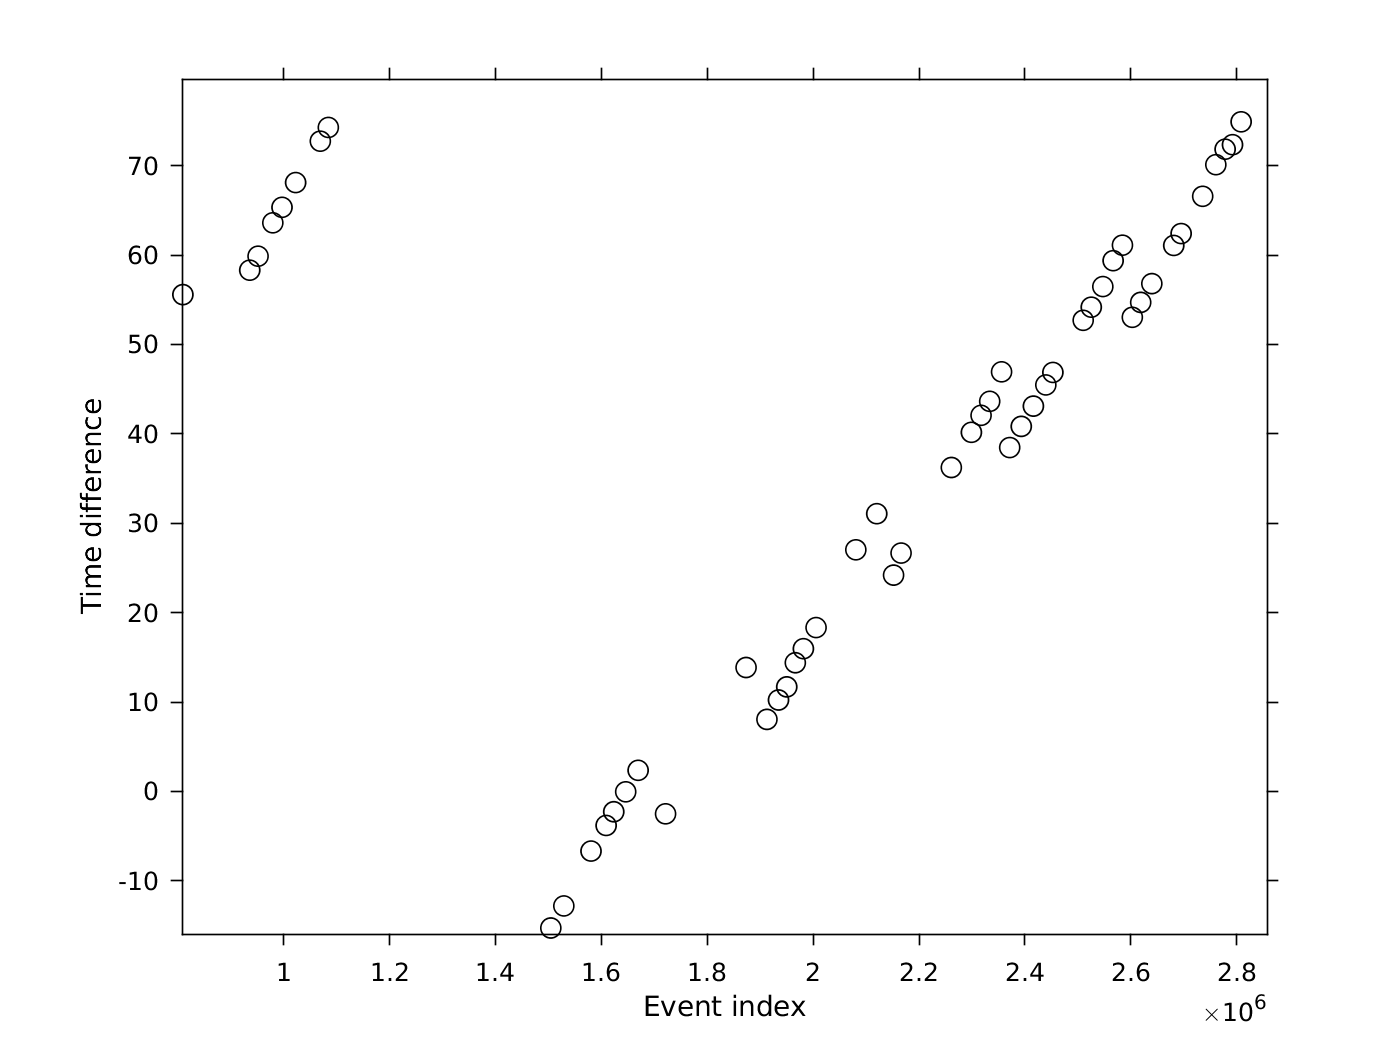

xlabel('Index')
ylabel('Time (sec)')

% find index of tLEDon in r:
IndOut = findseqmatchrev(tTriggerR, tLEDon, 0, 1);
figure;
subplot(2, 1, 1)
plot(IndOut);
subplot(2, 1, 2)
plot(diff(IndOut))
% Now tLEDon is mapped to MED time domain
tLEDonVideo         =       tLEDon(~isnan(IndOut));                   % This is LED on time in video time domain, in millisecond
tLEDonR             =       tTriggerR(IndOut(~isnan(IndOut)));         % This is the corresponding time in r , in millisecond

FrameInfo.tLEDon    =       tLEDonVideo;
FrameInfo.tLEDonR   =       tLEDonR;


Define the threshold
Threshold defined
Define the threshold
Threshold defined
#############################
######### Done correcting #######
#############################


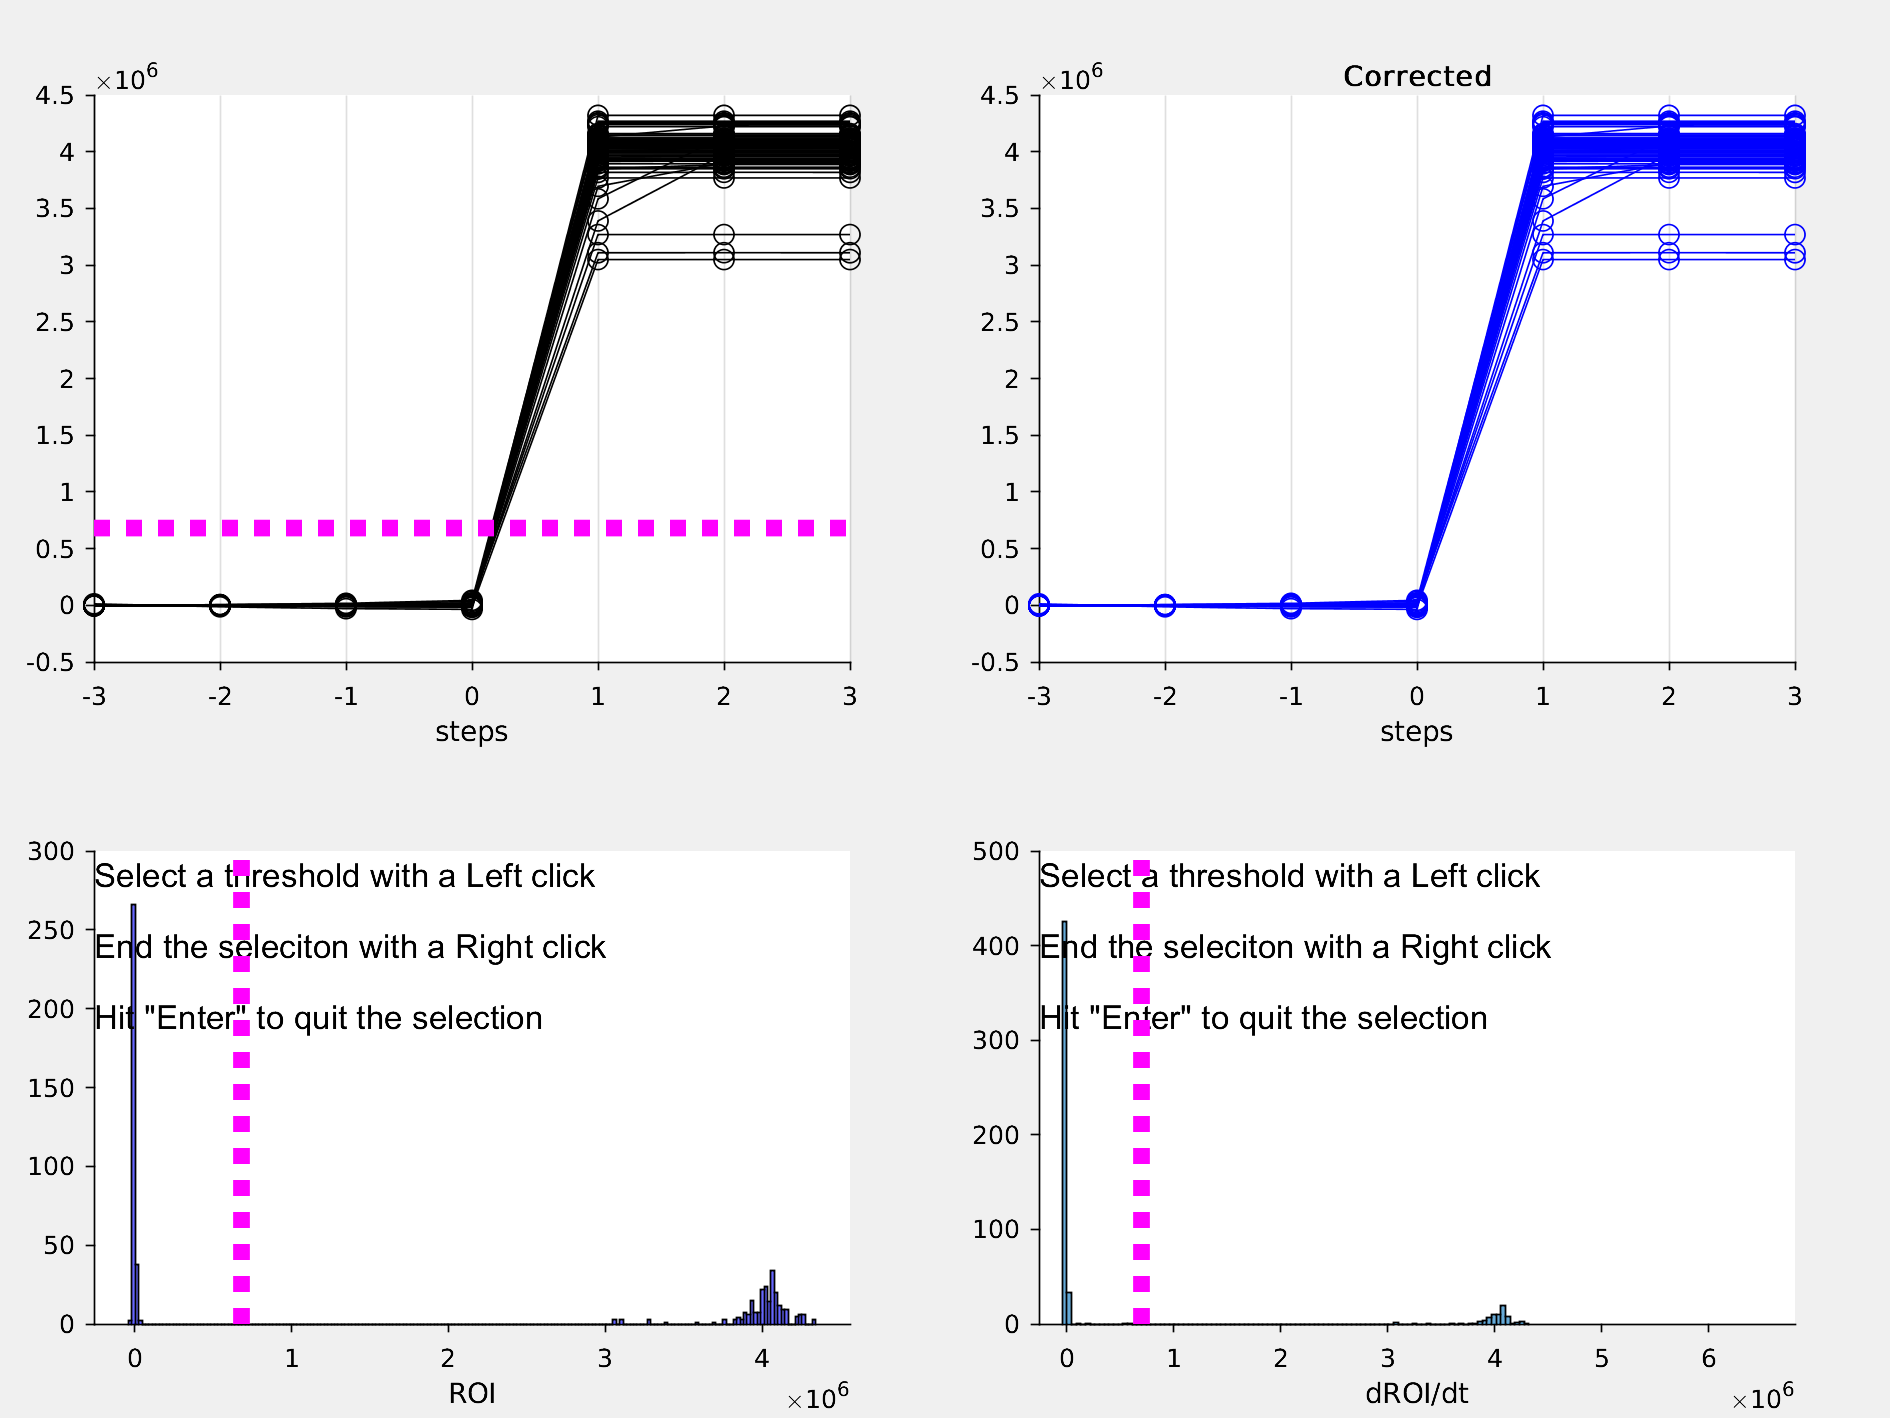

#############################
########## Please wait #########
#############################
Elapsed time is 1.147606 seconds.


% Map video frames to MED time domain
tFramesOut          =       MapVidFrameTimeToAnotherDomain(tLEDonVideo,tLEDonR, FrameInfo.tframe);
FrameInfo.tFrameR   =       tFramesOut;

% Check 
TimeDiff = tLEDonVideo(:) - tLEDonR(:);
disp('This demonstrate the drift (it is mitigated by re-alignment to each LED events)')
figure;
plot((tLEDonR - tLEDonR(1))/1000, TimeDiff - TimeDiff(1), 'ko');
xlabel('Time since the first event (s)'); ylabel('Time difference')
% Double check if LED time is well aligned

%% Empirically, some events are still not well aligned. In particually, in a small subset of trials, LED starts to light up at trigger time we need to revise these trials.
% some tLEDon need to be revised.

imhappy = 0;
while ~imhappy
    %   function tLEDnew = CorrectLEDtimeMED(TriggerTimeMED, FrameInfo)
    tLEDon          =       CorrectLEDtimeR(tLEDonR', FrameInfo); % update tLEDon
    % find index of tLEDon in MED domain:
    IndOut = findseqmatchrev(tTriggerR, tLEDon, 0, 1);
    tLEDonVideo         =       tLEDon(~isnan(IndOut));                   % This is LED on time in video time domain, in millisecond
    tLEDonR             =       tTriggerR(IndOut(~isnan(IndOut)));         % This is the corresponding time in r , in millisecond

    FrameInfo.tLEDon = tLEDonVideo;
    FrameInfo.tLEDonR = tLEDonR;

    % Map video frames to MED time domain
    tFramesOut = MapVidFrameTimeToAnotherDomain(tLEDonVideo, tLEDonR, FrameInfo.tframe);
    FrameInfo.tFrameR = tFramesOut;

    clc

    reply = input('Are you happy? Y/N [Y]', 's');
    if isempty(reply)
        reply = 'Y';
    end;
    if strcmp(reply, 'Y')  ||  strcmp(reply, 'y')
        imhappy = 1;
    else

ans = 'Extracting ......'

ans = '1000s frames extracted  1 '

ans = '1000s frames extracted  2 '

ans = '1000s frames extracted  3 '

ans = '1000s frames extracted  4 '

ans = '1000s frames extracted  5 '

ans = '1000s frames extracted  6 '

ans = '1000s frames extracted  7 '

ans = '1000s frames extracted  8 '

ans = '1000s frames extracted  9 '

ans = '1000s frames extracted 10 '

ans = '1000s frames extracted 11 '

ans = '1000s frames extracted 12 '

ans = '1000s frames extracted 13 '

ans = '1000s frames extracted 14 '

ans = '1000s frames extracted 15 '

ans = '1000s frames extracted 16 '

ans = '1000s frames extracted 17 '

ans = '1000s frames extracted 18 '

ans = '1000s frames extracted 19 '

ans = '1000s frames extracted 20 '

ans = '1000s frames extracted 21 '

ans = '1000s frames extracted 22 '

ans = '1000s frames extracted 23 '

ans = '1000s frames extracted 24 '

ans = '1000s frames extracted 25 '

ans = '1000s frames extracted 26 '

ans = '1000s frames extracted 27 '

ans = '1000s frames extracted 28 '

ans = '1000s frames extracted 29 '

ans = '1000s frames extracted 30 '

ans = '1000s frames extracted 31 '

ans = '1000s frames extracted 32 '

ans = '1000s frames extracted 33 '

ans = '1000s frames extracted 34 '

ans = '1000s frames extracted 35 '

ans = '1000s frames extracted 36 '

ans = '1000s frames extracted 37 '

ans = '1000s frames extracted 38 '

ans = '1000s frames extracted 39 '

ans = '1000s frames extracted 40 '

ans = '1000s frames extracted 41 '

ans = '1000s frames extracted 42 '

ans = '1000s frames extracted 43 '

ans = '1000s frames extracted 44 '

ans = '1000s frames extracted 45 '

ans = '1000s frames extracted 46 '

ans = '1000s frames extracted 47 '

ans = '1000s frames extracted 48 '

ans = '1000s frames extracted 49 '

ans = '1000s frames extracted 50 '

ans = '1000s frames extracted 51 '

ans = '1000s frames extracted 52 '

ans = '1000s frames extracted 53 '

ans = '1000s frames extracted 54 '

ans = '1000s frames extracted 55 '

ans = '1000s frames extracted 56 '

ans = '1000s frames extracted 57 '

ans = '1000s frames extracted 58 '

ans = '1000s frames extracted 59 '

ans = '1000s frames extracted 60 '

ans = '1000s frames extracted 61 '

ans = '1000s frames extracted 62 '

ans = '1000s frames extracted 63 '

ans = '1000s frames extracted 64 '

ans = '1000s frames extracted 65 '

ans = '1000s frames extracted 66 '

ans = '1000s frames extracted 67 '

ans = '1000s frames extracted 68 '

ans = '1000s frames extracted 69 '

ans = '1000s frames extracted 70 '

ans = '1000s frames extracted 71 '

ans = '1000s frames extracted 72 '

ans = '1000s frames extracted 73 '

ans = '1000s frames extracted 74 '

ans = '1000s frames extracted 75 '

ans = '1000s frames extracted 76 '

ans = '1000s frames extracted 77 '

ans = '1000s frames extracted 78 '

ans = '1000s frames extracted 79 '

ans = '1000s frames extracted 80 '

ans = '1000s frames extracted 81 '

ans = '1000s frames extracted 82 '

ans = '1000s frames extracted 83 '

ans = '1000s frames extracted 84 '

ans = '1000s frames extracted 85 '

ans = '1000s frames extracted 86 '

ans = '1000s frames extracted 87 '

ans = '1000s frames extracted 88 '

ans = '1000s frames extracted 89 '

ans = '1000s frames extracted 90 '

ans = '1000s frames extracted 91 '

ans = '1000s frames extracted 92 '

ans = '1000s frames extracted 93 '

ans = '1000s frames extracted 94 '

ans = '1000s frames extracted 95 '

ans = '1000s frames extracted 96 '

ans = '1000s frames extracted 97 '

ans = '1000s frames extracted 98 '

ans = '1000s frames extracted 99 '

ans = '1000s frames extracted 100 '

ans = '1000s frames extracted 101 '

ans = '1000s frames extracted 102 '

ans = '1000s frames extracted 103 '

ans = '1000s frames extracted 104 '

ans = '1000s frames extracted 105 '

ans = '1000s frames extracted 106 '

ans = '1000s frames extracted 107 '

ans = '1000s frames extracted 108 '

ans = '1000s frames extracted 109 '

ans = '1000s frames extracted 110 '

ans = '1000s frames extracted 111 '

ans = '1000s frames extracted 112 '

ans = '1000s frames extracted 113 '

ans = '1000s frames extracted 114 '

ans = '1000s frames extracted 115 '

ans = '1000s frames extracted 116 '

ans = '1000s frames extracted 117 '

ans = '1000s frames extracted 118 '

ans = '1000s frames extracted 119 '

ans = '1000s frames extracted 120 '

ans = '1000s frames extracted  1 '

ans = '1000s frames extracted  2 '

ans = '1000s frames extracted  3 '

ans = '1000s frames extracted  4 '

ans = '1000s frames extracted  5 '

ans = '1000s frames extracted  6 '

ans = '1000s frames extracted  7 '

ans = '1000s frames extracted  8 '

ans = '1000s frames extracted  9 '

ans = '1000s frames extracted 10 '

ans = '1000s frames extracted 11 '

ans = '1000s frames extracted 12 '

ans = '1000s frames extracted 13 '

ans = '1000s frames extracted 14 '

ans = '1000s frames extracted 15 '

ans = '1000s frames extracted 16 '

ans = '1000s frames extracted 17 '

ans = '1000s frames extracted 18 '

ans = '1000s frames extracted 19 '

ans = '1000s frames extracted 20 '

ans = '1000s frames extracted 21 '

ans = '1000s frames extracted 22 '

ans = '1000s frames extracted 23 '

ans = '1000s frames extracted 24 '

ans = '1000s frames extracted 25 '

ans = '1000s frames extracted 26 '

ans = '1000s frames extracted 27 '

ans = '1000s frames extracted 28 '

ans = '1000s frames extracted 29 '

ans = '1000s frames extracted 30 '

ans = '1000s frames extracted 31 '

ans = '1000s frames extracted 32 '

ans = '1000s frames extracted 33 '

ans = '1000s frames extracted 34 '

ans = '1000s frames extracted 35 '

ans = '1000s frames extracted 36 '

ans = '1000s frames extracted 37 '

ans = '1000s frames extracted 38 '

ans = '1000s frames extracted 39 '

ans = '1000s frames extracted 40 '

ans = '1000s frames extracted 41 '

ans = '1000s frames extracted 42 '

ans = '1000s frames extracted 43 '

ans = '1000s frames extracted 44 '

ans = '1000s frames extracted 45 '

ans = '1000s frames extracted 46 '

ans = '1000s frames extracted 47 '

ans = '1000s frames extracted 48 '

ans = '1000s frames extracted 49 '

ans = '1000s frames extracted 50 '

ans = '1000s frames extracted 51 '

ans = '1000s frames extracted 52 '

ans = '1000s frames extracted 53 '

ans = '1000s frames extracted 54 '

ans = '1000s frames extracted 55 '

ans = '1000s frames extracted 56 '

ans = '1000s frames extracted 57 '

ans = '1000s frames extracted 58 '

ans = '1000s frames extracted 59 '

ans = '1000s frames extracted 60 '

ans = '1000s frames extracted 61 '

ans = '1000s frames extracted 62 '

ans = '1000s frames extracted 63 '

ans = '1000s frames extracted 64 '

ans = '1000s frames extracted 65 '

ans = '1000s frames extracted 66 '

ans = '1000s frames extracted 67 '

ans = '1000s frames extracted 68 '

ans = '1000s frames extracted 69 '

ans = '1000s frames extracted 70 '

ans = '1000s frames extracted 71 '

ans = '1000s frames extracted 72 '

ans = '1000s frames extracted 73 '

ans = '1000s frames extracted 74 '

ans = '1000s frames extracted 75 '

ans = '1000s frames extracted 76 '

ans = '1000s frames extracted 77 '

ans = '1000s frames extracted 78 '

ans = '1000s frames extracted 79 '

ans = '1000s frames extracted 80 '

ans = '1000s frames extracted 81 '

ans = '1000s frames extracted 82 '

ans = '1000s frames extracted 83 '

ans = '1000s frames extracted 84 '

ans = '1000s frames extracted 85 '

ans = '1000s frames extracted 86 '

ans = '1000s frames extracted 87 '

ans = '1000s frames extracted 88 '

ans = '1000s frames extracted 89 '

ans = '1000s frames extracted 90 '

ans = '1000s frames extracted 91 '

ans = '1000s frames extracted 92 '

ans = '1000s frames extracted 93 '

ans = '1000s frames extracted 94 '

ans = '1000s frames extracted 95 '

ans = '1000s frames extracted 96 '

ans = '1000s frames extracted 97 '

ans = '1000s frames extracted 98 '

ans = '1000s frames extracted 99 '

ans = '1000s frames extracted 100 '

ans = '1000s frames extracted 101 '

ans = '1000s frames extracted 102 '

ans = '1000s frames extracted 103 '

ans = '1000s frames extracted 104 '

ans = '1000s frames extracted 105 '

ans = '1000s frames extracted 106 '

ans = '1000s frames extracted 107 '

ans = '1000s frames extracted 108 '

ans = '1000s frames extracted 109 '

ans = '1000s frames extracted 110 '

ans = '1000s frames extracted 111 '

ans = '1000s frames extracted 112 '

ans = '1000s frames extracted 113 '

ans = '1000s frames extracted 114 '

ans = '1000s frames extracted 115 '

ans = '1000s frames extracted 116 '

ans = '1000s frames extracted 117 '

ans = '1000s frames extracted 118 '

ans = '1000s frames extracted 119 '

ans = '1000s frames extracted 120 '

ans = '1000s frames extracted 121 '

ans = '1000s frames extracted 122 '

ans = '1000s frames extracted 123 '

ans = '1000s frames extracted 124 '

ans = '1000s frames extracted 125 '

ans = '1000s frames extracted 126 '

ans = '1000s frames extracted 127 '

ans = '1000s frames extracted 128 '

ans = '1000s frames extracted 129 '

ans = '1000s frames extracted 130 '

ans = '1000s frames extracted 131 '

ans = '1000s frames extracted 132 '

ans = '1000s frames extracted 133 '

ans = '1000s frames extracted 134 '

ans = '1000s frames extracted 135 '

ans = '1000s frames extracted 136 '

ans = '1000s frames extracted 137 '

ans = '1000s frames extracted 138 '

ans = '1000s frames extracted 139 '

ans = '1000s frames extracted 140 '

ans = '1000s frames extracted 141 '

ans = '1000s frames extracted 142 '

ans = '1000s frames extracted 143 '

ans = '1000s frames extracted 144 '

ans = '1000s frames extracted 145 '

ans = '1000s frames extracted 146 '

ans = '1000s frames extracted 147 '

ans = '1000s frames extracted 148 '

ans = '1000s frames extracted 149 '

ans = '1000s frames extracted 150 '

ans = '1000s frames extracted 151 '

ans = '1000s frames extracted 152 '

ans = '1000s frames extracted 153 '

ans = '1000s frames extracted 154 '

ans = '1000s frames extracted 155 '

ans = '1000s frames extracted 156 '

ans = '1000s frames extracted 157 '

ans = '1000s frames extracted 158 '

ans = '1000s frames extracted 159 '

ans = '1000s frames extracted 160 '

ans = '1000s frames extracted 161 '

ans = '1000s frames extracted 162 '

ans = '1000s frames extracted 163 '

ans = '1000s frames extracted 164 '

ans = '1000s frames extracted 165 '

ans = '1000s frames extracted 166 '

ans = '1000s frames extracted 167 '

ans = '1000s frames extracted 168 '

ans = '1000s frames extracted 169 '

ans = '1000s frames extracted 170 '

ans = '1000s frames extracted 171 '

ans = '1000s frames extracted 172 '

ans = '1000s frames extracted 173 '

ans = '1000s frames extracted 174 '

ans = '1000s frames extracted 175 '

ans = '1000s frames extracted 176 '

ans = '1000s frames extracted 177 '

ans = '1000s frames extracted 178 '

ans = '1000s frames extracted 179 '

Elapsed time is 2635.655155 seconds.


        imhappy =0;
    end
end;
save FrameInfo FrameInfo
r.Video = FrameInfo;
save('RTarrayAll.mat', 'r')


% Update FrameInfo to add top view:
FrameInfo = GetSeqFrameInfoTopView(FrameInfo, topviews);
save FrameInfo FrameInfo
r.Video = FrameInfo;
save('RTarrayAll.mat', 'r')

## Load wave data and align the data to r

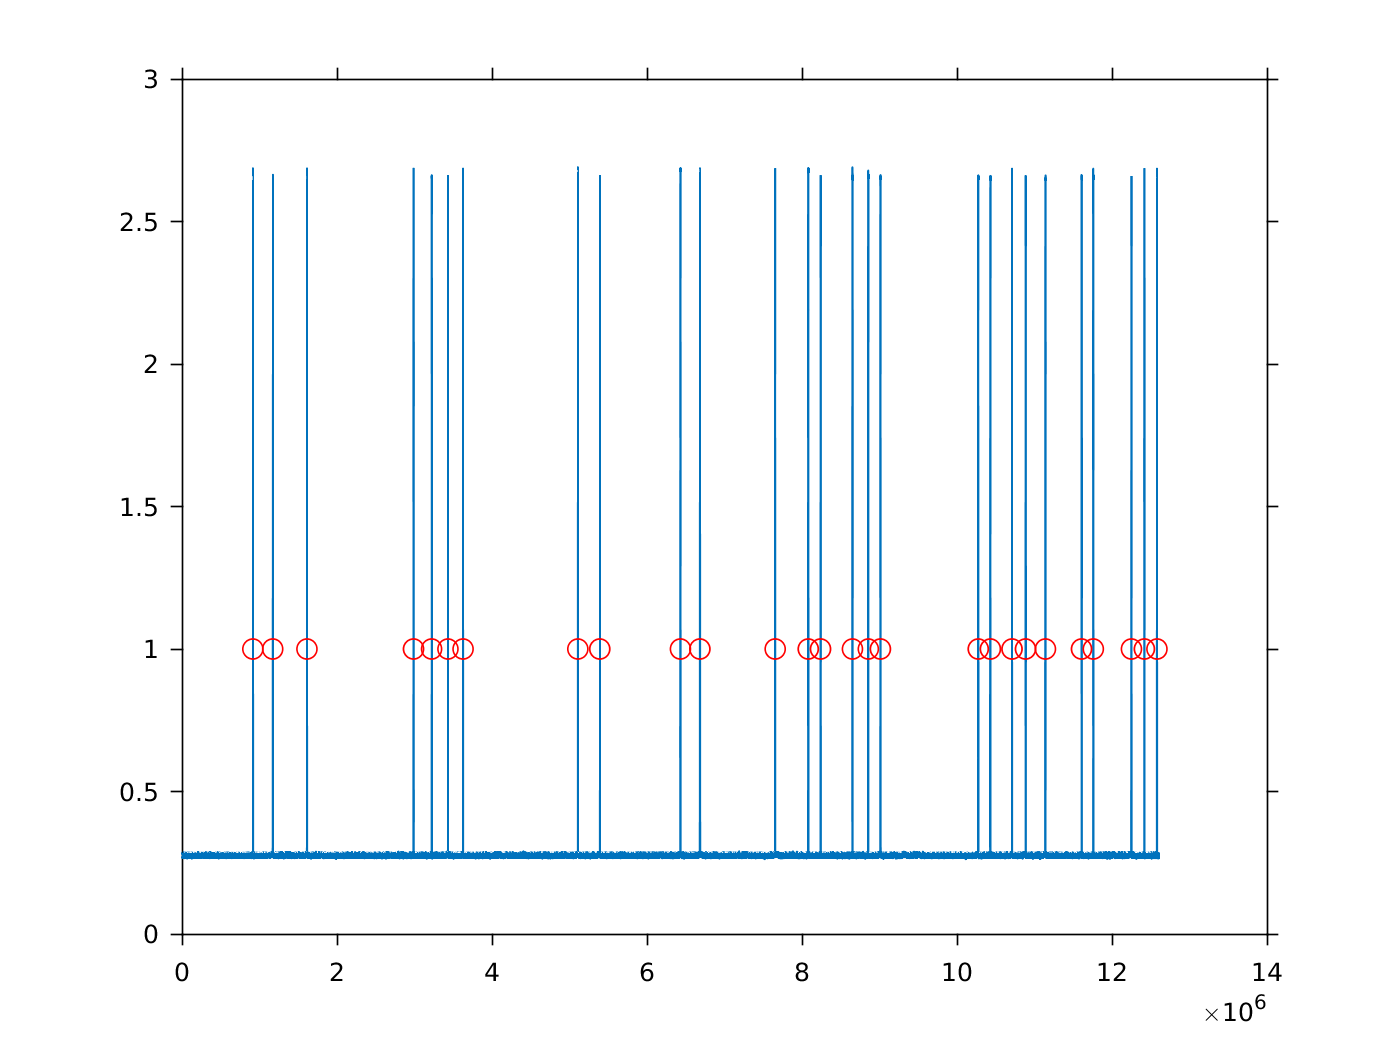

#############################
########## Please wait #########
#############################
Elapsed time is 0.272523 seconds.


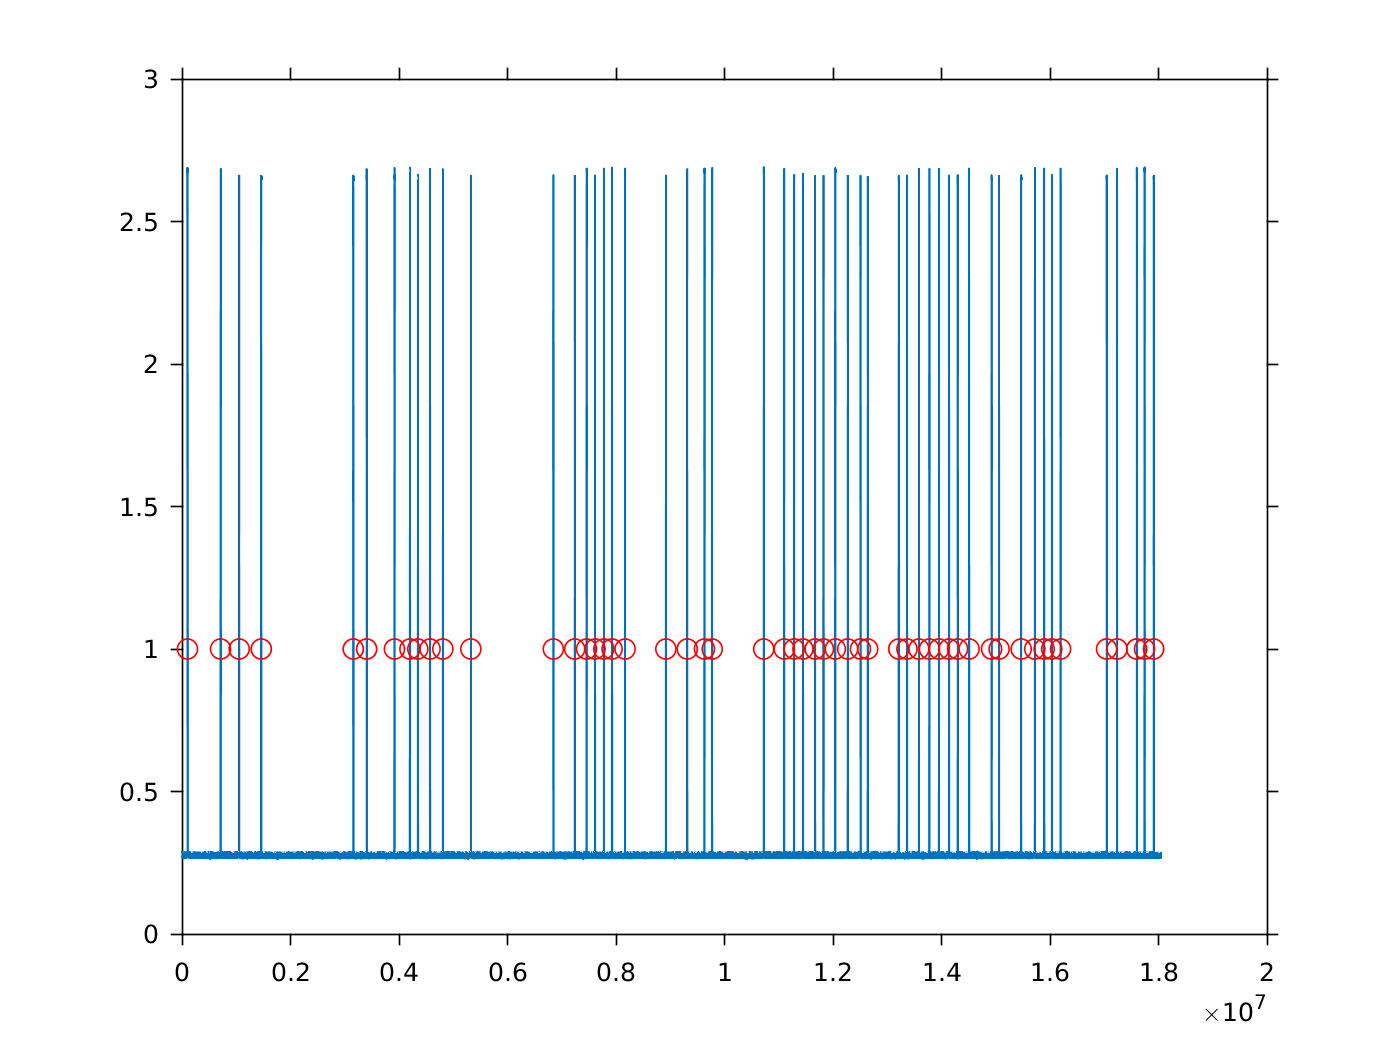

#############################
########## Please wait #########
#############################
Elapsed time is 0.528214 seconds.


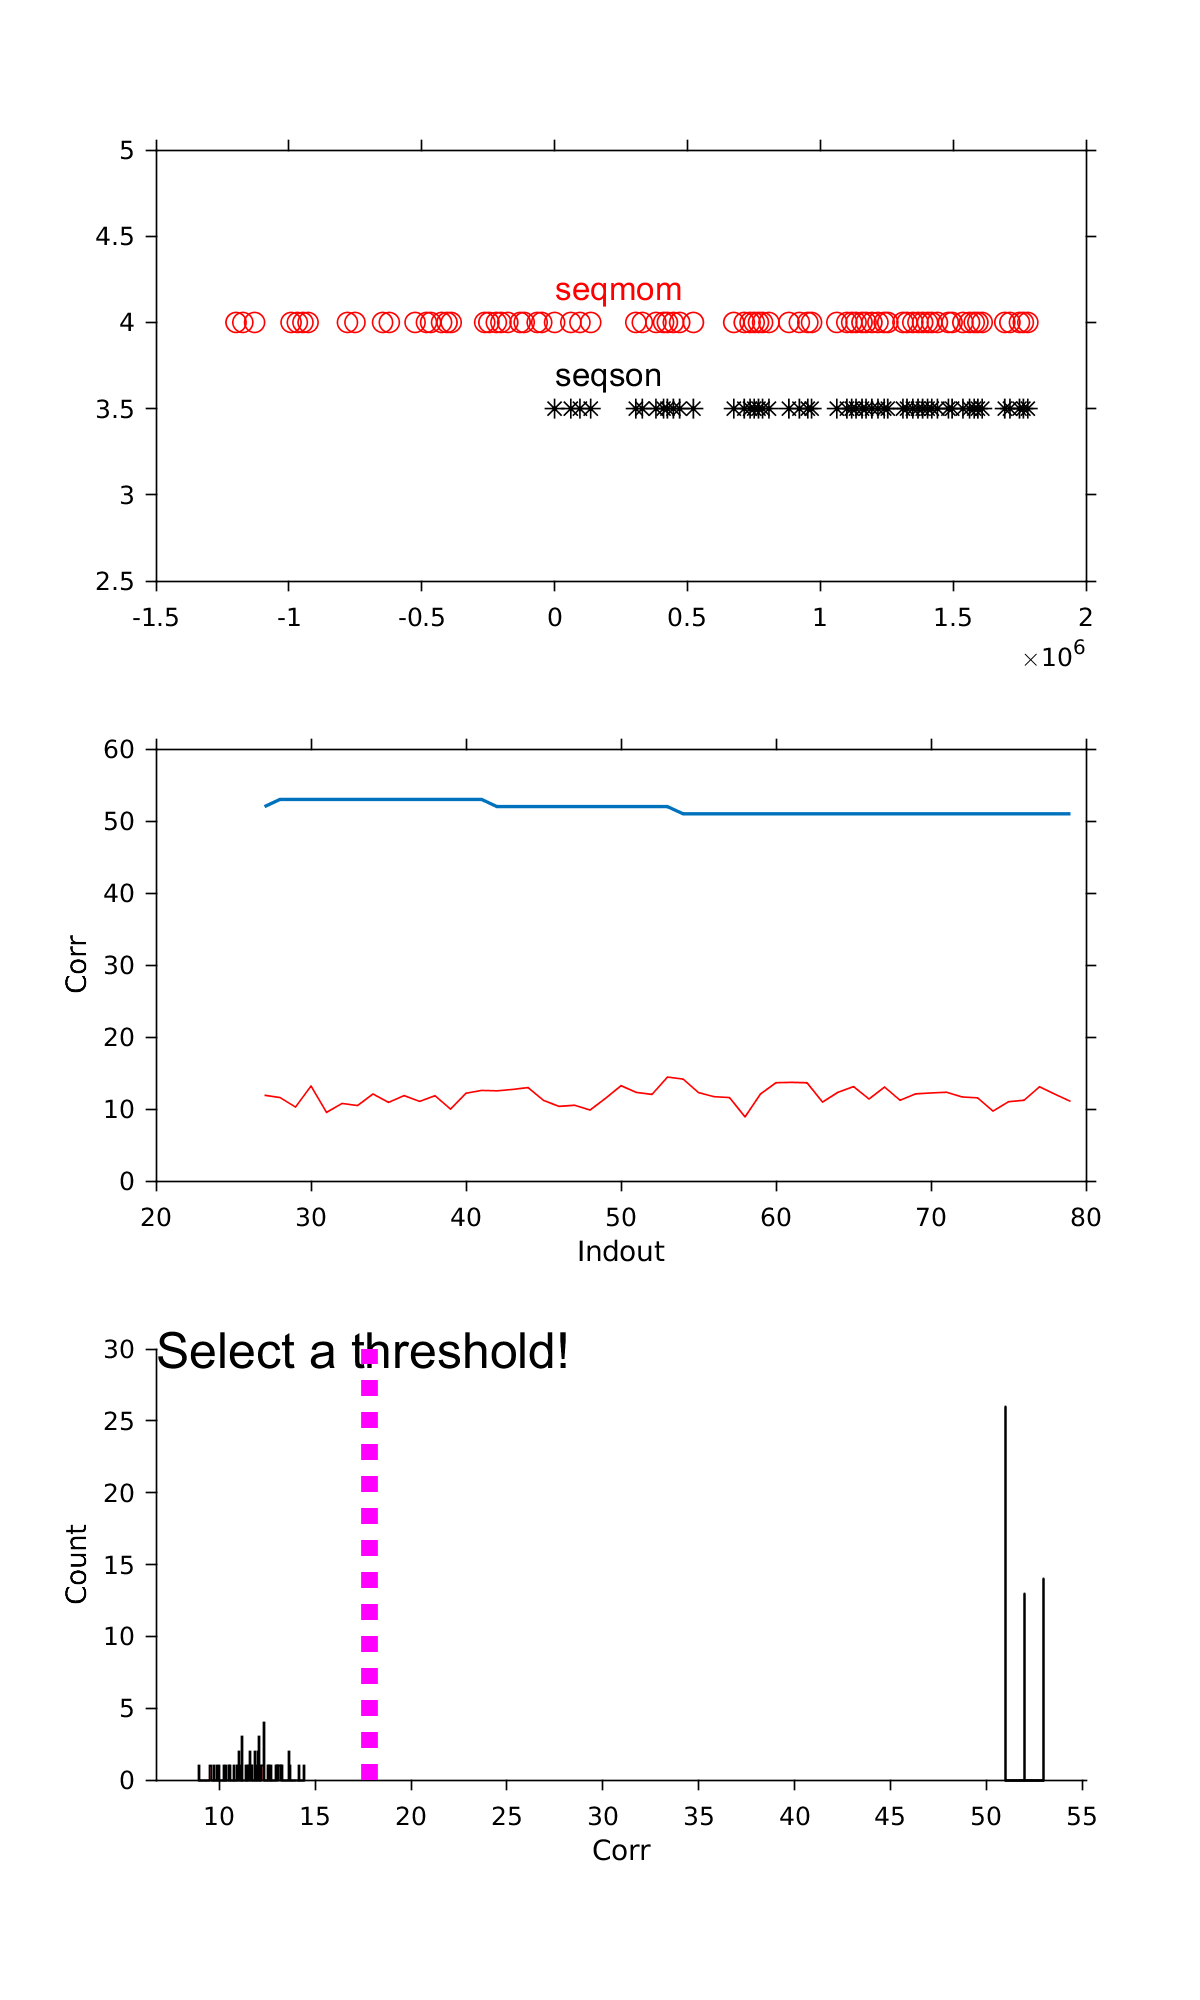

% h5file = dir('*.h5');
% disp(h5file.name)


h5fileNames = arrayfun(@(x)x.name, h5files, 'UniformOutput', false);
WSOut = [];
for i =1:length(h5fileNames)
    iWSOut                      =       ReadH5Opto(h5fileNames{i});
    iWSOut                      =       MapWave2R(iWSOut, tTriggerR);
    if isempty(WSOut)
        WSOut                   =       iWSOut;
    else
        WSOut.Time              =       [WSOut.Time iWSOut.Time];
        WSOut.Signals           =       [WSOut.Signals; iWSOut.Signals];
        WSOut.TriggerTimeWS     =       [WSOut.TriggerTimeWS iWSOut.TriggerTimeWS];
        WSOut.TriggerTimeWS2R   =       [WSOut.TriggerTimeWS2R; iWSOut.TriggerTimeWS2R];
        WSOut.TimeInR           =       [WSOut.TimeInR iWSOut.TimeInR];
    end;
end;
save('WSOut.mat', 'WSOut', '-v7.3' ) 

## Make video clips

% Note: Preload these files
load('RTarrayAll.mat')
load('WSOut.mat')

% Run this line of code if you haven't done so already (this produce RArrayTable.csv)
% >> MakeBehaviorTableFromR(r)

%  make video based on press, cued, correct responses

bTable           =       readtable(dir('RArrayTable*.csv').name);
indPressCued     =       find(strcmp(bTable.Outcome, 'Correct') & bTable.CueIndex == 1);
tPressCued       =       bTable.tPress(indPressCued);
RTPressCued      =       bTable.RT(indPressCued);

MakeEphysVideoDualViewLED(r, bTable, WSOut, tPressCued, 'eventName', 'CuedPress', 'timeRange', [-1500 2500], 'reMake', 0)
 

indPressUnCued    =       find(strcmp(bTable.Outcome, 'Correct') & bTable.CueIndex == 0);
tPressUnCued      =       bTable.tPress(indPressUnCued);
RTPressUnCued     =       bTable.RT(indPressUnCued);
MakeEphysVideoDualViewLED(r, bTable, WSOut, tPressUnCued, 'eventName', 'UnCuedPress', 'timeRange', [-1500 2500],'reMake', 0)



